# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.5 函数方程可视化

#### 2.5.2  三元方程

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

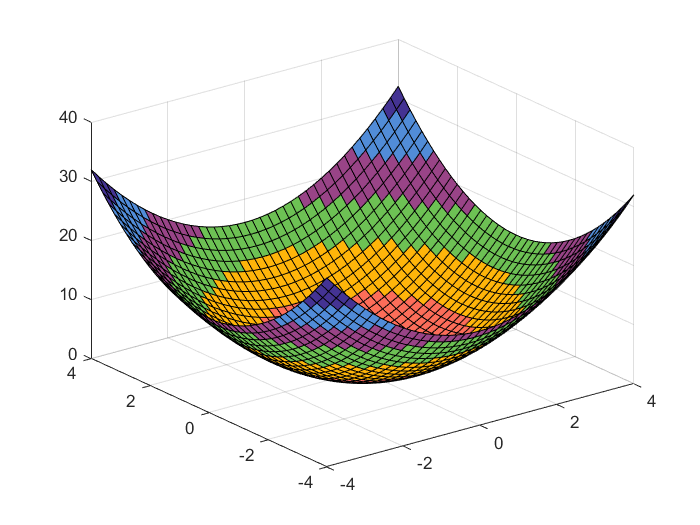

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 方式一
figure;
[x, y] = meshgrid(-4:0.2:4);
z = x.^2 + y.^2;
figure
surf(x, y, z);
% 设置颜色
colormap(all_themes{1});

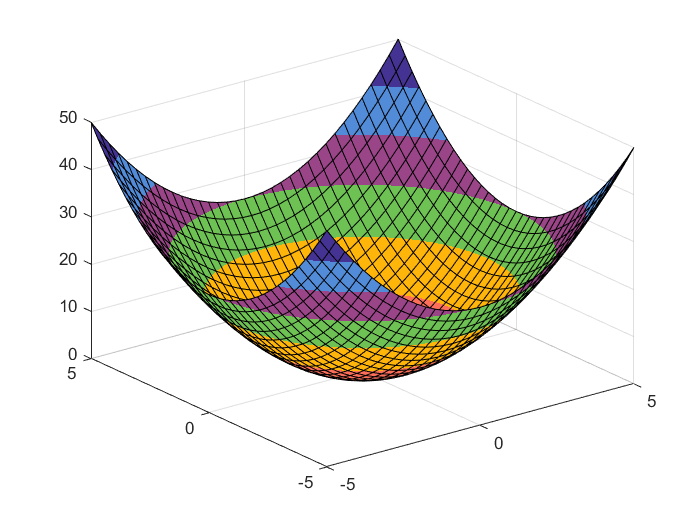

% 方式二
figure
fsurf(@(x, y) x.^2 + y.^2);
colormap(all_themes{1});

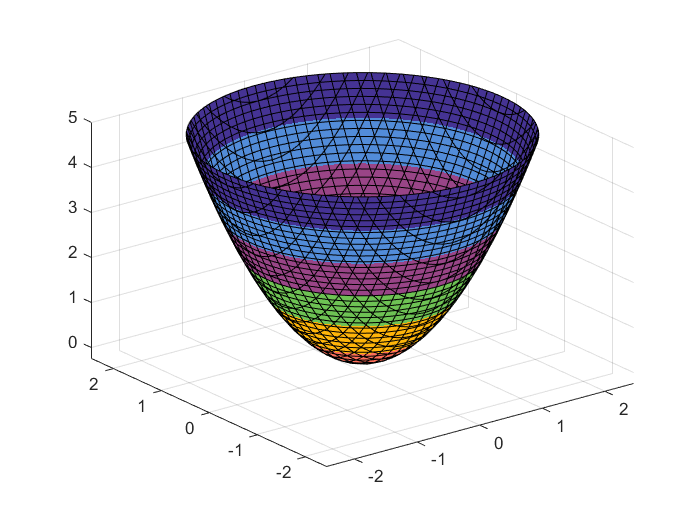

% 方式三
figure
f = @(x,y,z) x.^2 + y.^2 - z;
fimplicit3(f);
colormap(all_themes{1});

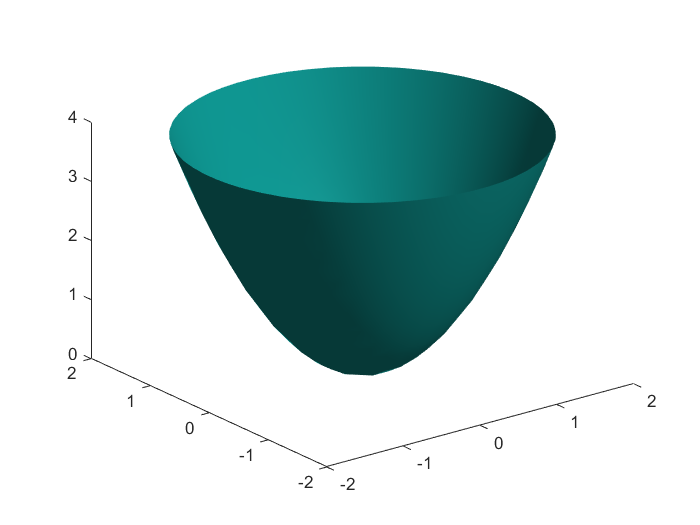

% 方式四
figure
[x, y, z] = meshgrid(linspace(-4, 4, 40));
isosurface(x, y, z, f(x, y, z), 0);

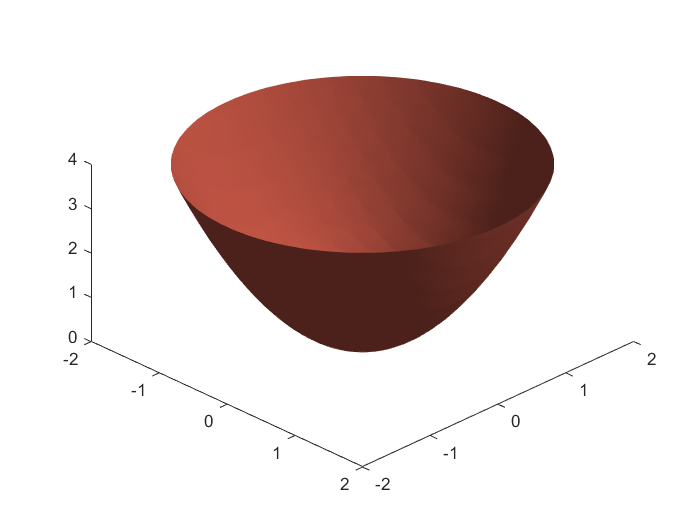

figure
nexttile
p = patch(isosurface(x, y, z, f(x, y, z), 0));
p.FaceColor = all_colors(1, :);
p.EdgeColor = 'none';
view(45, 45);
% 一定要打光
camlight 
lighting gouraud